##  ECE 537 : Assignment 7

Group 9 - Ashlynn Steeves, Derrell D'Souza

close all;
clear all;
clc;

**Task 1.** Load the Exercise 7 Data Set, which consists of drawn data from two classes. For the first measurement feature vector apply an appropriate statistical goodness-of-fit test to determine whether or not the this feature is Gaussian.

load('Exercise_7_Data.mat')

Class_1 = data(class==0,:);
Class_2 = data(class==1,:);

C1_F1 = Class_1(:,1);
h_C1 = chi2gof(C1_F1)

h_C1 = 1


C2_F1 = Class_2(:,1);
h_C2 = chi2gof(C2_F1)

h_C2 = 0

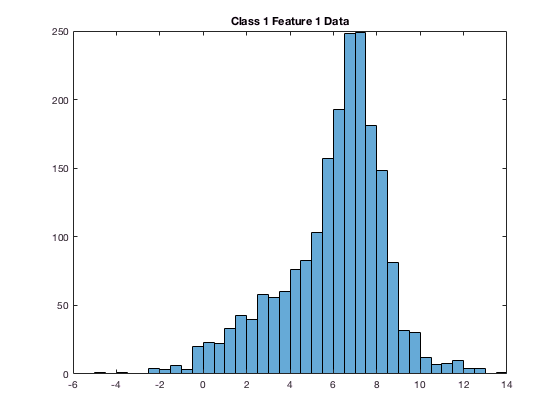


figure(1)
histogram(C1_F1)
title('Class 1 Feature 1 Data')

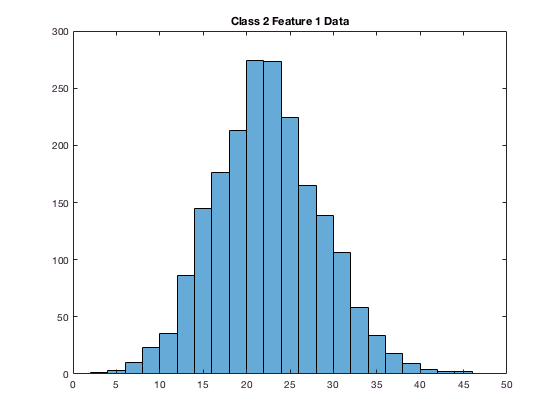


figure(2)
histogram(C2_F1)
title('Class 2 Feature 1 Data')

**Comments: **Using the chi-squared goodness of fit test which tests the null hypothesis that the data in F1 comes from a normal distribution with mean and varriance estimated from F1. For Class 1 The test returns an h value of 1 which indicates that it has rejected the null hypothesis and the data is not normally distributed. For Class 2 The test returns an h value of 0 which indicates that it has accepted the null hypothesis and the data is  normally distributed. Based on the histogram of the data in Class 1 F1 the data seems to be drawn from an exponential distribution, this theiry will be tested in future tasks. 

**Task 2.** Determine the Bayes classification error rate for the data if the analysis is based solely on data taken from the first measurement feature. Note you can no longer simply assume that the data for each class is Gaussian distributed. Moreover, Bayes classification does not make this assumption but, instead applied generally to any class distribution.

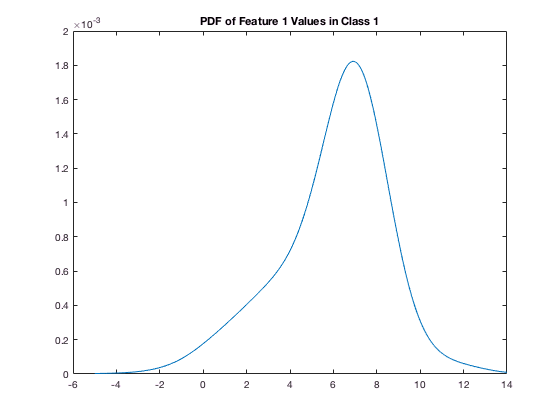


pd1 = fitdist(C1_F1,'kernel','BandWidth',1);
x = linspace(floor(min(C1_F1)), ceil(max(C1_F1)), 2000); 
y1 = pdf(pd1, x);
y1 = y1./sum(y1);
figure(2)
plot(x, y1); 
title('PDF of Feature 1 Values in Class 1')

**Task 3**. Determine the Bayes classification error rate for the data if the analysis is based solely on data taken from the second measurement feature.

% Confirming that the second feature is drawn from gaussian data 
C1_F2 = Class_1(:,2);
h_C1 = chi2gof(C1_F2)

h_C1 = 0


C2_F2 = Class_2(:,2);
h_C2 = chi2gof(C2_F2)

h_C2 = 0

**Task 4.** Determine the Bayes classification error rate for the data if the analysis is based on all of the available measurement features, where you will also need to apply proper data normalization.

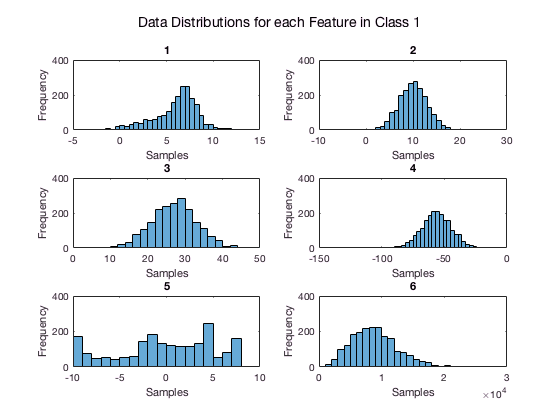

% Class 1 Histograms 
figure(3)
for i = 1:6
    subplot(3,2,i)
    histogram(Class_1(:,i));
    title(i)
    xlabel('Samples');
    ylabel('Frequency');
end 
suptitle('Data Distributions for each Feature in Class 1')

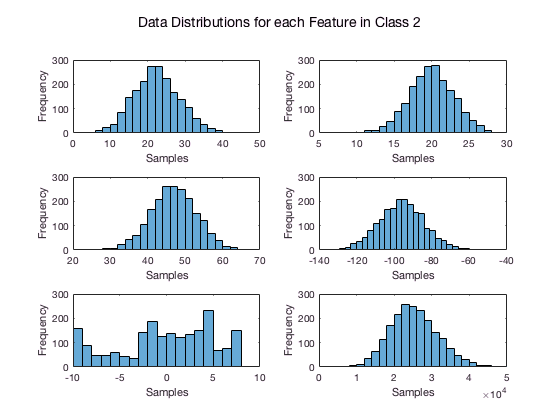


% Class 2 Histograms 
figure(4)
for i = 1:6
    subplot(3,2,i)
    histogram(Class_2(:,i));
    title(i)
    xlabel('Samples');
    ylabel('Frequency');
end 
suptitle('Data Distributions for each Feature in Class 2')